# 3-D  Trajectory planning in task space passes through at least four via points

## Construct The Robot

clc; clear;
robot = importrobot('Franka_Emika_Panda.urdf');

robot.DataFormat = 'column';

Show details of the robot to validate the input properties. The robot should have two non-fixed joints, where the link bodies are connected to their parent bodies via a revolute joint, and the end effector is connected to its parent body via a fixed joint.


panda_model()
M;
B;
S;

The velocity profile has four parameters:

- **End Time **— Duration of each segment between two waypoints

- **Peak Velocity **— Peak velocity for a each segment

- **Acceleration Time** — Time spent in the acceleration and deceleration phases of each segment

- **Peak Acceleration **— Magnitude of the acceleration applied during the acceleration and deceleration phases of each segment

peakVelocities = [150, 150, 150, 150, 180, 180, 180]'.*pi/180;
vpa(peakVelocities', 5)

$$ans = \left(\begin{array}{ccccccc} 2.618 & 2.618 & 2.618 & 2.618 & 3.1416 & 3.1416 & 3.1416 \end{array}\right)$$

peakAcceleration = [850, 425, 570, 700, 850, 1140, 1140]'.*pi/180;
vpa(peakAcceleration', 5)

$$ans = \left(\begin{array}{ccccccc} 14.835 & 7.4176 & 9.9484 & 12.217 & 14.835 & 19.897 & 19.897 \end{array}\right)$$

### **Task-Space Trajectories**

A *task-space trajectory* contains waypoints that represent end-effector motion in 3-D space. Generate a minimum-jerk trajectory to connect waypoints in free space. The purpose of this trajectory profile is to create a smooth trajectory with minimal jerky motion.Then generate the joint configurations of the Franka Emika Panda robot using inverse kinematics.

t0 = 0; %Start Time
sampleRate = 60; % Sample Rate
tf = 1.3; %Final Time
t = linspace(t0, tf, sampleRate); % Time
tstp = sampleRate;
dt = (tf-t0)/tstp

dt = 0.0217


numSamples = length(t);


First, create a set of waypoints, and then create the minimum-jerk trajectory using [`minjerkpolytraj`](https://www.mathworks.com/help/robotics/ref/minjerkpolytraj.html).

rng default
% frankaWaypoints = [q1 q2 q3 q4];
frankaTimepoints = linspace(t(1),t(end),3);


### Four arbitrary via points

frankaSpaceWaypoints = [0.5 0.25 0.35; 0.75 0 0.35; 0.6 -0.2 0.35; 0.5 -0.5 0.35]';
frankaTimepoints = linspace(t(1),t(end),4);
[pos,vel] = minjerkpolytraj(frankaSpaceWaypoints,frankaTimepoints,numSamples);

Use the [`inverseKinematics`](docid:robotics_ref#bvdhj7x-1) function to create an inverse kinematics solver and solve for configurations that reach the desired end-effector positions over the trajectory.

rng(0) % Seed the RNG so the inverse kinematics solution is consistent
ik = inverseKinematics(RigidBodyTree=robot);
ik.SolverParameters.AllowRandomRestart = false;
q = zeros(7,numSamples);
weights = [0 0 0 1 1 1]; % Prioritize position over orientation
initialGuess = [0, 0, 0, -pi/2, 0, 0, 0]'; % Choose an inital guess within the robot joint limits

trajs = cell(1, size(pos,2));

for i = 1:size(pos,2)
    targetPose = trvec2tform(pos(:,i)')*eul2tform([0, 0, pi]);
    trajs{i} = targetPose;

    q(:,i) = ik('b_frame',targetPose,weights,initialGuess);
    initialGuess = q(:,i); % Use the last result as the next initial guess
end


for i = 1:size(pos,2)
    q1(:,i) = IK_Body(trajs{i}, initialGuess, [1e-3, 1e-3], B, M);
    initialGuess = q1(:,i); % Use the last result as the next initial guess
end

Show the results using the robot model.

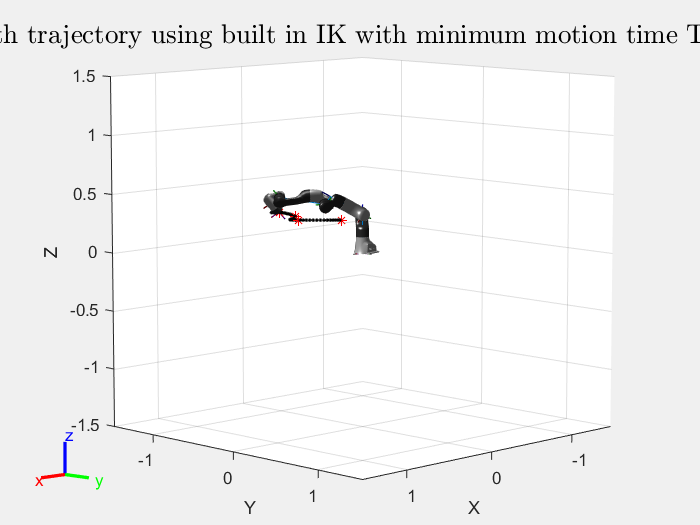

clf; figure;
set(gcf,'Visible','on')
show(robot, 'Visuals','on');
hold on;
rc = rateControl(sampleRate);
str = "Smooth trajectory using built in IK with minimum motion time T = " + num2str(tf) + " s";
title(str, FontSize=16, Interpreter="latex");
trajs_result = cell(1, numSamples);
for i = 1:numSamples
    show(robot,q(:,i),FastUpdate=true, PreservePlot=false);
    drawnow;
    hold on;

    T = FK_BodyForm(B, M, q(:,i));
    trajs_result{i} = T;
    X = T(1, 4);
    Y = T(2, 4);
    Z = T(3, 4);
    plot3(X, Y, Z, 'black.' );
    plot3(frankaSpaceWaypoints(1, :), frankaSpaceWaypoints(2, :), frankaSpaceWaypoints(3, :), 'r*');
    waitfor(rc);
    pause(0.01)
end

trajs_result{1}

ans =    -0.1709    0.3999   -0.9005    0.5000
    0.1831   -0.8851   -0.4278    0.2500
   -0.9681   -0.2380    0.0780    0.3500
         0         0         0    1.0000


trajs_result{20}

ans =     0.9139    0.0112   -0.4059    0.7404
    0.0353   -0.9980    0.0520    0.0110
   -0.4045   -0.0618   -0.9124    0.3500
         0         0         0    1.0000


trajs_result{40}

ans =     0.3677   -0.2977   -0.8810    0.6050
   -0.1938   -0.9511    0.2405   -0.1934
   -0.9095    0.0823   -0.4074    0.3500
         0         0         0    1.0000


trajs_result{60}

ans =     0.4339   -0.6545   -0.6192    0.5000
   -0.6938   -0.6811    0.2337   -0.5000
   -0.5747    0.3282   -0.7496    0.3500
         0         0         0    1.0000


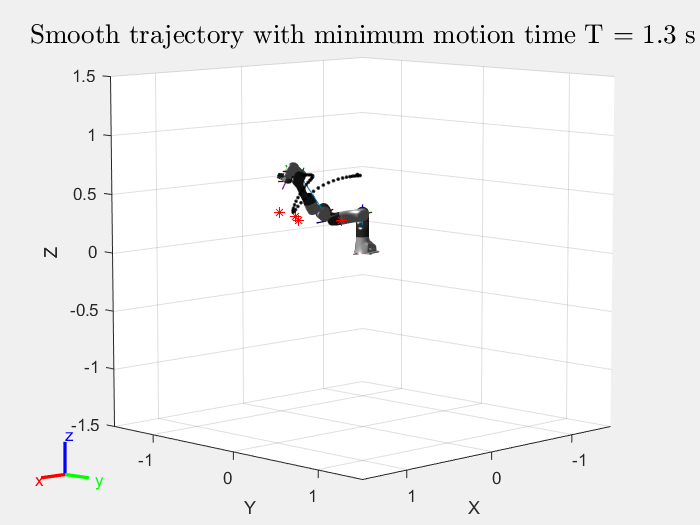

clf; figure;
set(gcf,'Visible','on')
show(robot, 'Visuals','on');
hold on;
rc = rateControl(sampleRate);
str = "Smooth trajectory with minimum motion time T = " + num2str(tf) + " s";
title(str, FontSize=16, Interpreter="latex");
trajs_result1 = cell(1, numSamples);
for i = 1:numSamples
    show(robot,q1(:,i),FastUpdate=true, PreservePlot=false);
    drawnow;
    hold on;

    T = FK_BodyForm(B, M, q1(:,i));
    trajs_result1{i} = T;
    X = T(1, 4);
    Y = T(2, 4);
    Z = T(3, 4);
    plot3(X, Y, Z, 'black.' );
    plot3(frankaSpaceWaypoints(1, :), frankaSpaceWaypoints(2, :), frankaSpaceWaypoints(3, :), 'r*');
    waitfor(rc);
    pause(0.01)
end

trajs_result1{5}

ans =     0.6990    0.0334    0.7143    0.3119
   -0.0262   -0.9971    0.0721    0.2794
    0.7146   -0.0691   -0.6961    0.7100
         0         0         0    1.0000


trajs_result1{20}

ans =     0.9447   -0.1520    0.2906    0.7033
   -0.0253   -0.9172   -0.3976    0.0773
    0.3270    0.3683   -0.8703    0.5616
         0         0         0    1.0000


trajs_result1{40}

ans =     0.8889   -0.1733    0.4241    0.5277
    0.0547   -0.8789   -0.4738   -0.0607
    0.4549    0.4444   -0.7717    0.6894
         0         0         0    1.0000


trajs_result1{60}

ans =     0.9949   -0.1006    0.0032    0.5126
   -0.0830   -0.8375   -0.5401   -0.4000
    0.0570    0.5371   -0.8416    0.6213
         0         0         0    1.0000


To examine the different joint positions and velocities, visualize these results by plotting all the dimensions against time. Use the `helperPlotTaskSpaceTraj` helper function to plot the task-space trajectory and its waypoints.

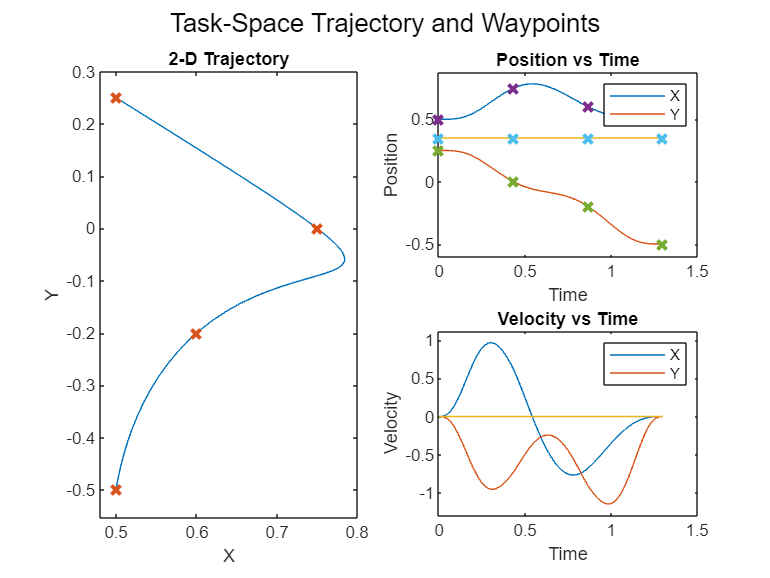

helperPlotTaskSpaceTraj('Task-Space Trajectory and Waypoints', ...
    t,pos,vel,frankaSpaceWaypoints,frankaTimepoints);

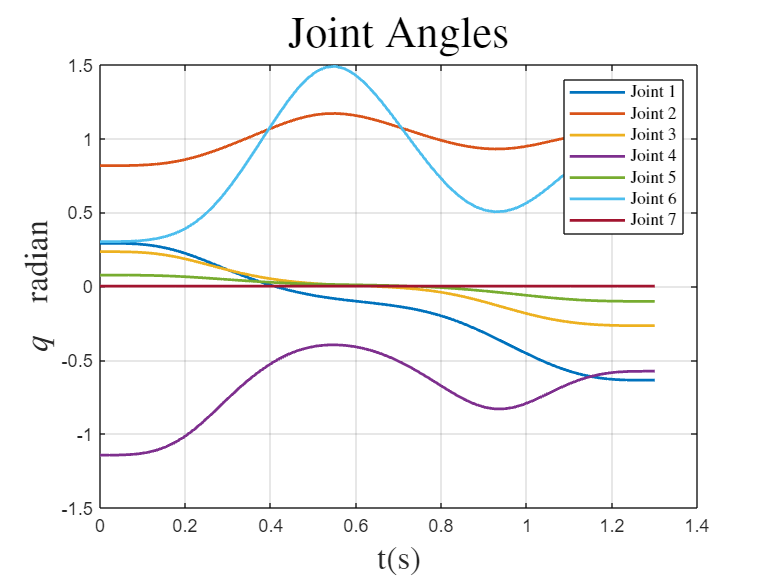

figure;

plot(t,q, LineWidth=1.5)
title('Joint Angles', Interpreter='latex', FontSize=24);
legend('Joint 1','Joint 2','Joint 3','Joint 4','Joint 5','Joint 6','Joint 7', 'Interpreter', 'latex');
ylabel('$q \quad \textrm{radian}$', Interpreter='latex', FontSize=18);
xlabel('t(s)', Interpreter='latex', FontSize=18);
grid on;

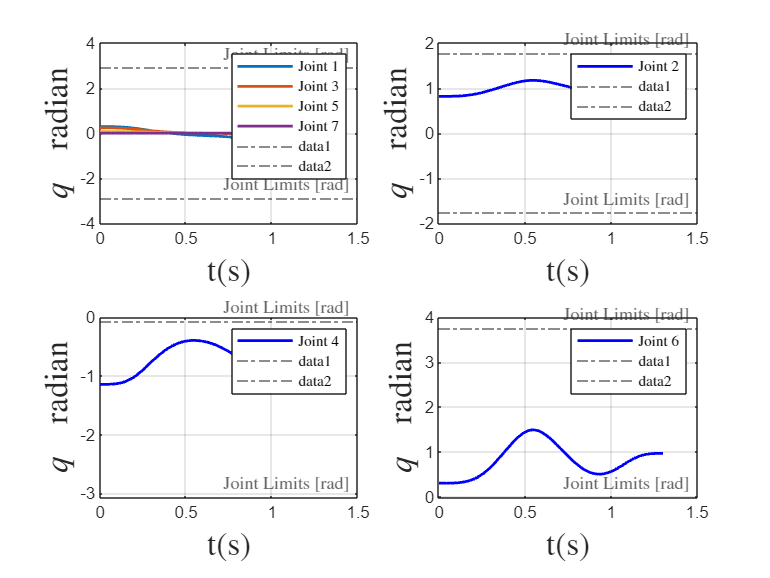

clf; figure;
title('Joint Angles', Interpreter='latex', FontSize=24);

subplot(2, 2, 1);
plot(t,q(1, :), LineWidth=1.5)
hold on;
plot(t,q(3, :), LineWidth=1.5)
hold on;
plot(t,q(5, :), LineWidth=1.5)
hold on;
plot(t,q(7, :), LineWidth=1.5)

legend('Joint 1','Joint 3','Joint 5','Joint 7', 'Interpreter', 'latex');
yline(panda.qlim(1, :),'-.','Joint Limits [rad]', Interpreter='latex');

ylabel('$q \quad \textrm{radian}$', Interpreter='latex', FontSize=18);
xlabel('t(s)', Interpreter='latex', FontSize=18);
grid on;


subplot(2, 2, 2);
plot(t,q(2, :), LineWidth=1.5, Color='b')
legend('Joint 2', 'Interpreter', 'latex');
yline(panda.qlim(2, :),'-.','Joint Limits [rad]', Interpreter='latex');
ylabel('$q \quad \textrm{radian}$', Interpreter='latex', FontSize=18);
xlabel('t(s)', Interpreter='latex', FontSize=18);
grid on;

subplot(2, 2, 3);
plot(t,q(4, :), LineWidth=1.5, Color='b')
legend('Joint 4', 'Interpreter', 'latex');
yline(panda.qlim(4, :),'-.','Joint Limits [rad]', Interpreter='latex');
ylabel('$q \quad \textrm{radian}$', Interpreter='latex', FontSize=18);
xlabel('t(s)', Interpreter='latex', FontSize=18);
grid on;

subplot(2, 2, 4);
plot(t,q(6, :), LineWidth=1.5, Color='b')
legend('Joint 6', 'Interpreter', 'latex');
yline(panda.qlim(6, :),'-.','Joint Limits [rad]', Interpreter='latex');
ylabel('$q \quad \textrm{radian}$', Interpreter='latex', FontSize=18);
xlabel('t(s)', Interpreter='latex', FontSize=18);
grid on;

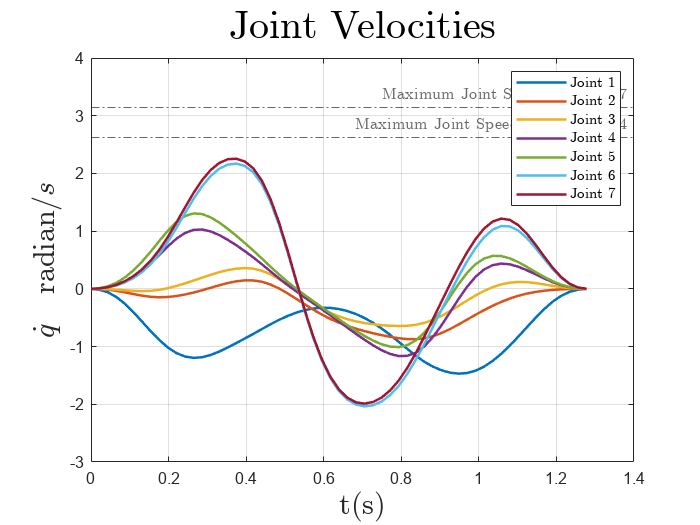


qd  = diff(q, 1, 2)./dt;
qd = smoothdata(qd,"movmean","SmoothingFactor",0.5);
qdd = diff(qd, 1, 2)./dt;
qdd = smoothdata(qdd,"movmean","SmoothingFactor",0.5);

figure;
td = t(1: numSamples-1);
plot(td,qd, LineWidth=1.5)



yline(peakVelocities(1),'-.','Maximum Joint Speed, J1, J2, J3, J4', Interpreter='latex');
yline(peakVelocities(5),'-.','Maximum Joint Speed, J5, J6, J7', Interpreter='latex');



title('Joint Velocities', Interpreter='latex', FontSize=24);
legend('Joint 1','Joint 2','Joint 3','Joint 4','Joint 5','Joint 6','Joint 7', 'Interpreter', 'latex');
ylabel("$\dot{q} \quad {\textrm{radian}}/{s}$", Interpreter='latex', FontSize=18);
xlabel('t(s)', Interpreter='latex', FontSize=18);
grid on;

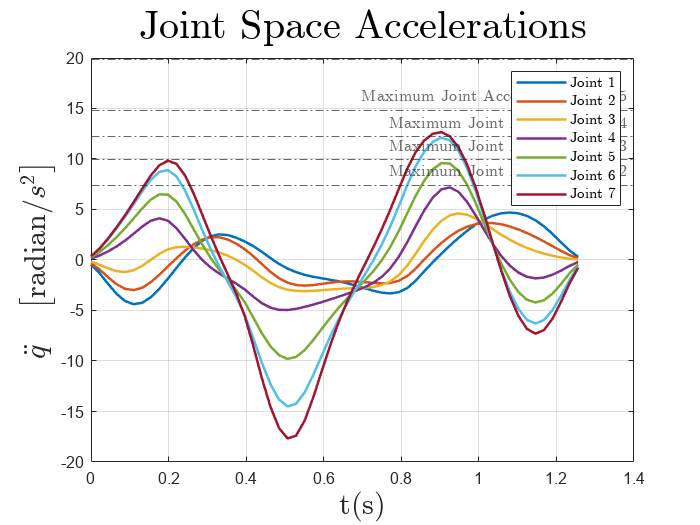


figure;
tdd = t(1:numSamples-2);

plot(tdd,qdd, LineWidth=1.5)

hold on;

yline(peakAcceleration(1),'-.','Maximum Joint Acceleration, J1, J5', Interpreter='latex');
yline(peakAcceleration(2),'-.','Maximum Joint Acceleration, J2', Interpreter='latex');
yline(peakAcceleration(3),'-.','Maximum Joint Acceleration, J3', Interpreter='latex');
yline(peakAcceleration(4),'-.','Maximum Joint Acceleration, J4', Interpreter='latex');
yline(peakAcceleration(6),'-.','Maximum Joint Acceleration, J6, J7', Interpreter='latex');

title('Joint Space Accelerations', Interpreter='latex', FontSize=24);
legend('Joint 1','Joint 2','Joint 3','Joint 4','Joint 5','Joint 6','Joint 7', 'Interpreter', 'latex');
ylabel('$\ddot{q} \quad \left[ \textrm{radian}/ s^2 \right]$', Interpreter='latex', FontSize=18);
xlabel('t(s)', Interpreter='latex', FontSize=18);

grid on;

## Compare Various Trajectory Profiles

Gemerate trajectories using different tools, and then compare them using both task- and joint-space visualization.

wpts = frankaSpaceWaypoints;
tpts = 0:(size(wpts,2)-1);

% Derived quantities.
sampleRate = 20;
t = tpts(1):1/sampleRate:tpts(end);
numSamples = length(t)

numSamples = 61

### Cubic Polynomial Trajectories

Some use cases can require a more general polynomial trajectory. The [`cubicpolytraj`](docid:robotics_ref#mw_e0bccbba-7851-4785-9549-cd84984711dd) and [`quinticpolytraj`](docid:robotics_ref#mw_e126a472-347c-4b6f-9c00-b593b7c66124) functions are general tools for creating interpolating piecewise polynomials. Like the previous trajectory tools, they return position, velocity, and acceleration, as well as the piecewise polynomial object. 

In the default case, these functions use zero-valued boundary conditions, resulting in trajectories that stop at every waypoint.

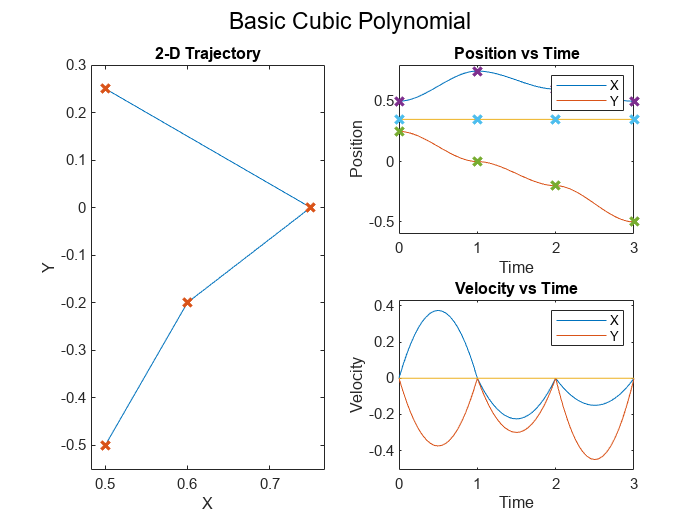

[pos,vel] = cubicpolytraj(wpts,tpts,t);
helperPlotTaskSpaceTraj('Basic Cubic Polynomial',t,pos,vel,wpts,tpts);

Use the [`inverseKinematics`](docid:robotics_ref#bvdhj7x-1) function to create an inverse kinematics solver and solve for configurations that reach the desired end-effector positions over the trajectory.

rng(0) % Seed the RNG so the inverse kinematics solution is consistent
ik = inverseKinematics(RigidBodyTree=robot);
ik.SolverParameters.AllowRandomRestart = false;
q = zeros(7,numSamples);
weights = [0 0 0 1 1 1]; % Prioritize position over orientation
initialGuess = [0, 0, 0, -pi/2, 0, 0, 0]'; % Choose an inital guess within the robot joint limits

trajs = cell(1, size(pos,2));

for i = 1:size(pos,2)
    targetPose = trvec2tform(pos(:,i)')*eul2tform([0, 0, pi]);
    trajs{i} = targetPose;

    q(:,i) = ik('b_frame',targetPose,weights,initialGuess);
    initialGuess = q(:,i); % Use the last result as the next initial guess
end


for i = 1:size(pos,2)
    q1(:,i) = IK_Body(trajs{i}, initialGuess, [1e-3, 1e-3], B, M);
    initialGuess = q1(:,i); % Use the last result as the next initial guess
end

Show the results using the robot model.

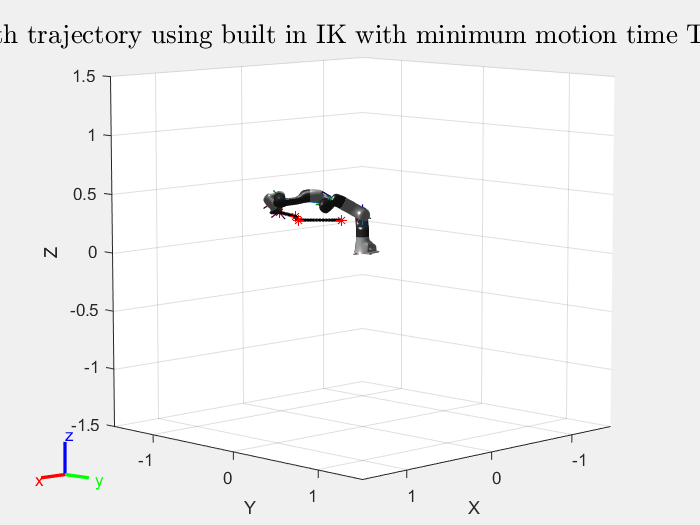

clf; figure;
set(gcf,'Visible','on')
show(robot, 'Visuals','on');
hold on;
rc = rateControl(sampleRate);
str = "Smooth trajectory using built in IK with minimum motion time T = " + num2str(tf) + " s";
title(str, FontSize=16, Interpreter="latex");
trajs_result = cell(1, numSamples);
for i = 1:numSamples
    show(robot,q(:,i),FastUpdate=true, PreservePlot=false);
    drawnow;
    hold on;

    T = FK_BodyForm(B, M, q(:,i));
    trajs_result{i} = T;
    X = T(1, 4);
    Y = T(2, 4);
    Z = T(3, 4);
    plot3(X, Y, Z, 'black.' );
    plot3(frankaSpaceWaypoints(1, :), frankaSpaceWaypoints(2, :), frankaSpaceWaypoints(3, :), 'r*');
    waitfor(rc);
    pause(0.01)
end

trajs_result{1}

ans =    -0.1709    0.3999   -0.9005    0.5000
    0.1831   -0.8851   -0.4278    0.2500
   -0.9681   -0.2380    0.0780    0.3500
         0         0         0    1.0000


trajs_result{20}

ans =     0.9348   -0.0009   -0.3551    0.7482
    0.0191   -0.9984    0.0527    0.0018
   -0.3546   -0.0561   -0.9333    0.3500
         0         0         0    1.0000


trajs_result{40}

ans =     0.3550   -0.3047   -0.8838    0.6011
   -0.2068   -0.9476    0.2436   -0.1986
   -0.9117    0.0963   -0.3994    0.3500
         0         0         0    1.0000


trajs_result{60}

ans =     0.4316   -0.6503   -0.6252    0.5007
   -0.6930   -0.6827    0.2317   -0.4978
   -0.5775    0.3333   -0.7453    0.3500
         0         0         0    1.0000


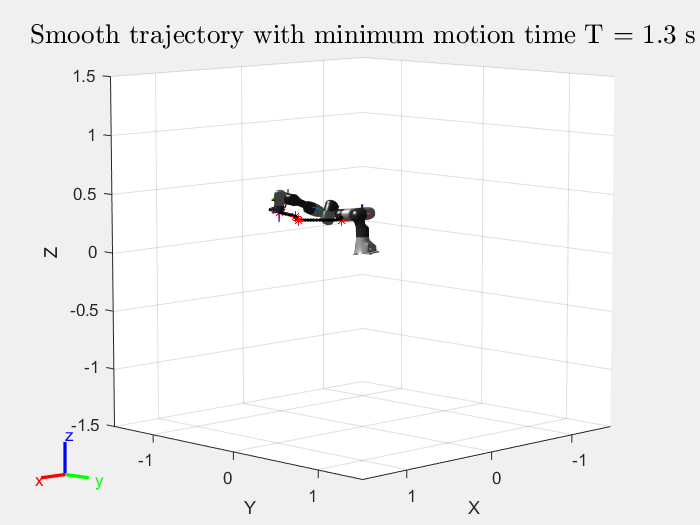

clf; figure;
set(gcf,'Visible','on')
show(robot, 'Visuals','on');
hold on;
rc = rateControl(sampleRate);
str = "Smooth trajectory with minimum motion time T = " + num2str(tf) + " s";
title(str, FontSize=16, Interpreter="latex");
trajs_result1 = cell(1, numSamples);
for i = 1:numSamples
    show(robot,q1(:,i),FastUpdate=true, PreservePlot=false);
    drawnow;
    hold on;

    T = FK_BodyForm(B, M, q1(:,i));
    trajs_result1{i} = T;
    X = T(1, 4);
    Y = T(2, 4);
    Z = T(3, 4);
    plot3(X, Y, Z, 'black.' );
    plot3(frankaSpaceWaypoints(1, :), frankaSpaceWaypoints(2, :), frankaSpaceWaypoints(3, :), 'r*');
    waitfor(rc);
    pause(0.01)
end

trajs_result1{5}

ans =     1.0000   -0.0001    0.0086    0.5257
    0.0000   -1.0000   -0.0072    0.2239
    0.0086    0.0072   -0.9999    0.3527
         0         0         0    1.0000


trajs_result1{20}

ans =     1.0000   -0.0000    0.0001    0.7480
   -0.0000   -1.0000   -0.0000    0.0018
    0.0001    0.0000   -1.0000    0.3500
         0         0         0    1.0000


trajs_result1{40}

ans =     1.0000   -0.0000    0.0020    0.6010
    0.0000   -1.0000   -0.0065   -0.1984
    0.0020    0.0065   -1.0000    0.3525
         0         0         0    1.0000


trajs_result1{60}

ans =     1.0000    0.0000    0.0000    0.5007
    0.0000   -1.0000   -0.0000   -0.4978
    0.0000    0.0000   -1.0000    0.3500
         0         0         0    1.0000


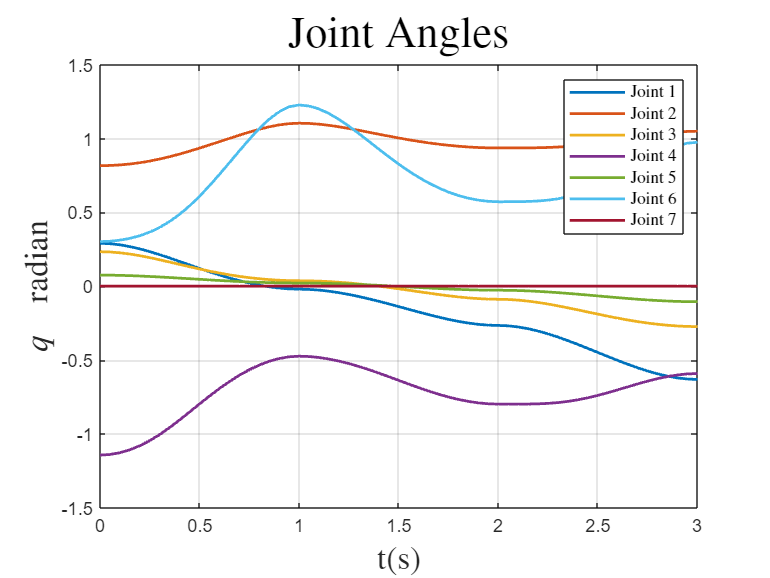


figure;

plot(t,q, LineWidth=1.5)
title('Joint Angles', Interpreter='latex', FontSize=24);
legend('Joint 1','Joint 2','Joint 3','Joint 4','Joint 5','Joint 6','Joint 7', 'Interpreter', 'latex');
ylabel('$q \quad \textrm{radian}$', Interpreter='latex', FontSize=18);
xlabel('t(s)', Interpreter='latex', FontSize=18);
grid on;

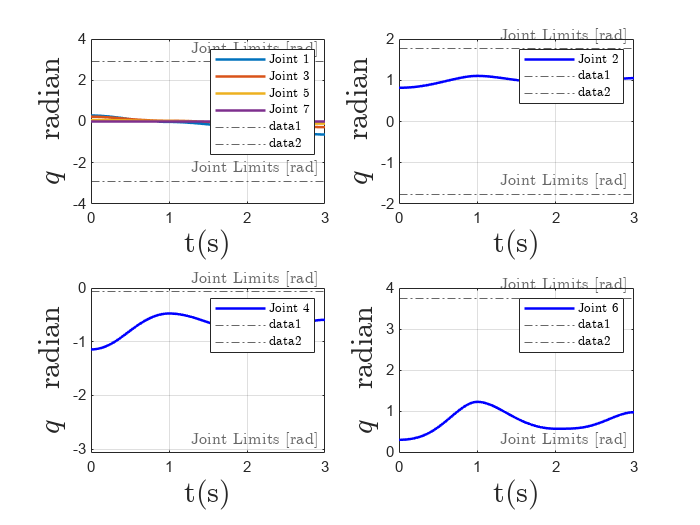

clf; figure;
title('Joint Angles', Interpreter='latex', FontSize=24);

subplot(2, 2, 1);
plot(t,q(1, :), LineWidth=1.5)
hold on;
plot(t,q(3, :), LineWidth=1.5)
hold on;
plot(t,q(5, :), LineWidth=1.5)
hold on;
plot(t,q(7, :), LineWidth=1.5)

legend('Joint 1','Joint 3','Joint 5','Joint 7', 'Interpreter', 'latex');
yline(panda.qlim(1, :),'-.','Joint Limits [rad]', Interpreter='latex');

ylabel('$q \quad \textrm{radian}$', Interpreter='latex', FontSize=18);
xlabel('t(s)', Interpreter='latex', FontSize=18);
grid on;


subplot(2, 2, 2);
plot(t,q(2, :), LineWidth=1.5, Color='b')
legend('Joint 2', 'Interpreter', 'latex');
yline(panda.qlim(2, :),'-.','Joint Limits [rad]', Interpreter='latex');
ylabel('$q \quad \textrm{radian}$', Interpreter='latex', FontSize=18);
xlabel('t(s)', Interpreter='latex', FontSize=18);
grid on;

subplot(2, 2, 3);
plot(t,q(4, :), LineWidth=1.5, Color='b')
legend('Joint 4', 'Interpreter', 'latex');
yline(panda.qlim(4, :),'-.','Joint Limits [rad]', Interpreter='latex');
ylabel('$q \quad \textrm{radian}$', Interpreter='latex', FontSize=18);
xlabel('t(s)', Interpreter='latex', FontSize=18);
grid on;

subplot(2, 2, 4);
plot(t,q(6, :), LineWidth=1.5, Color='b')
legend('Joint 6', 'Interpreter', 'latex');
yline(panda.qlim(6, :),'-.','Joint Limits [rad]', Interpreter='latex');
ylabel('$q \quad \textrm{radian}$', Interpreter='latex', FontSize=18);
xlabel('t(s)', Interpreter='latex', FontSize=18);
grid on;

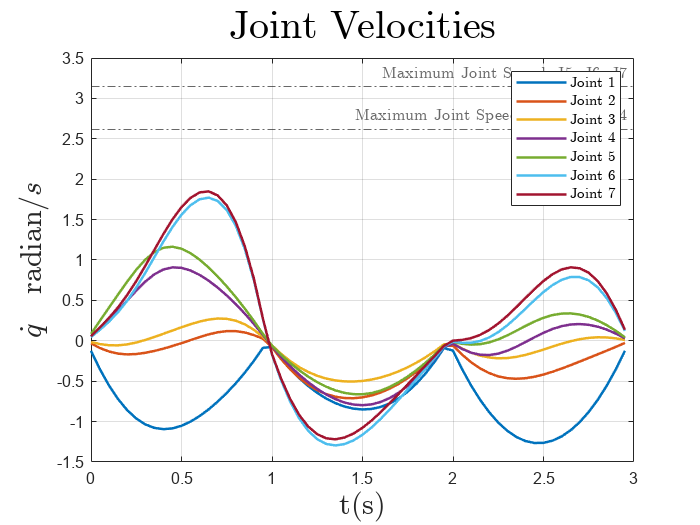


qd  = diff(q, 1, 2)./dt;
qd = smoothdata(qd,"movmean","SmoothingFactor",0.5);
qdd = diff(qd, 1, 2)./dt;
qdd = smoothdata(qdd,"movmean","SmoothingFactor",0.5);

figure;
td = t(1: numSamples-1);
plot(td,qd, LineWidth=1.5)



yline(peakVelocities(1),'-.','Maximum Joint Speed, J1, J2, J3, J4', Interpreter='latex');
yline(peakVelocities(5),'-.','Maximum Joint Speed, J5, J6, J7', Interpreter='latex');



title('Joint Velocities', Interpreter='latex', FontSize=24);
legend('Joint 1','Joint 2','Joint 3','Joint 4','Joint 5','Joint 6','Joint 7', 'Interpreter', 'latex');
ylabel("$\dot{q} \quad {\textrm{radian}}/{s}$", Interpreter='latex', FontSize=18);
xlabel('t(s)', Interpreter='latex', FontSize=18);
grid on;

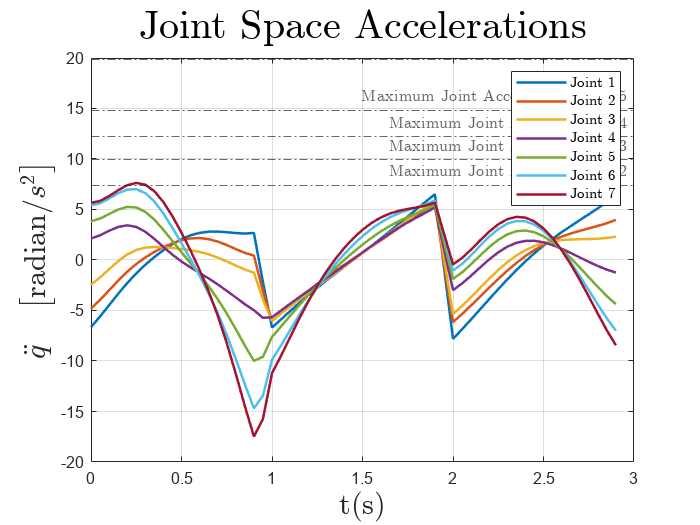


figure;
tdd = t(1:numSamples-2);

plot(tdd,qdd, LineWidth=1.5)

hold on;

yline(peakAcceleration(1),'-.','Maximum Joint Acceleration, J1, J5', Interpreter='latex');
yline(peakAcceleration(2),'-.','Maximum Joint Acceleration, J2', Interpreter='latex');
yline(peakAcceleration(3),'-.','Maximum Joint Acceleration, J3', Interpreter='latex');
yline(peakAcceleration(4),'-.','Maximum Joint Acceleration, J4', Interpreter='latex');
yline(peakAcceleration(6),'-.','Maximum Joint Acceleration, J6, J7', Interpreter='latex');

title('Joint Space Accelerations', Interpreter='latex', FontSize=24);
legend('Joint 1','Joint 2','Joint 3','Joint 4','Joint 5','Joint 6','Joint 7', 'Interpreter', 'latex');
ylabel('$\ddot{q} \quad \left[ \textrm{radian}/ s^2 \right]$', Interpreter='latex', FontSize=18);
xlabel('t(s)', Interpreter='latex', FontSize=18);

grid on;

You can use these functions to design an interpolating polynomial with custom boundary behavior. For example, by using these functions together with other piecewise polynomial tools like [`spline`](docid:matlab_ref#bvjdpi3), [`pchip`](docid:matlab_ref#bvjbxbd), or [`makima`](docid:matlab_ref#mw_fda58e3c-de78-4b86-beb0-98bd56d7d7b4), you can create smooth profiles with desirable motion at the waypoints.

This example code derives boundary conditions from one of the built-in piecewise polynomial functions in MATLAB. Select a polynomial function to see how it affects the cubic polynomial velocity profile. The code uses a helper file to compute the velocity.

smoothPP = spline(tpts,wpts);
smoothVelPP = mkpp(smoothPP.breaks,robotics.core.internal.polyCoeffsDerivative(smoothPP.coefs),size(wpts,1));
smoothVelPoly = ppval(smoothVelPP,tpts);


Use the derived velocity as the boundary condition for the inner waypoints. Leave the outside boundary conditions as zero velocity to ensure the trajectory starts and ends at zero velocity

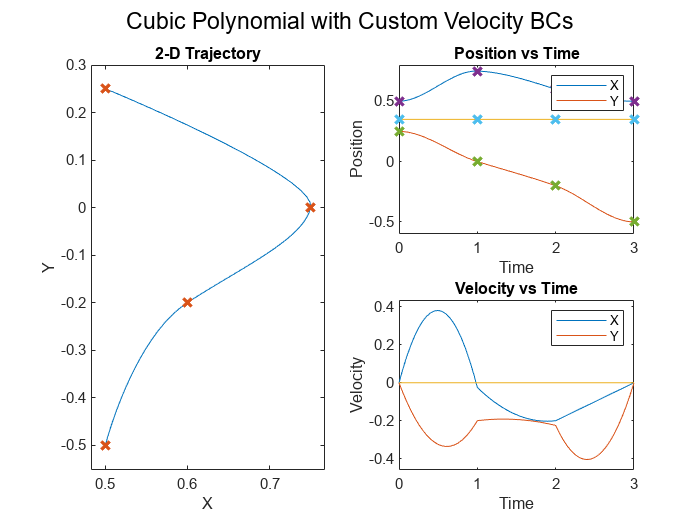

boundaryVel = zeros(size(smoothVelPoly));
boundaryVel(:,2:end-1) = smoothVelPoly(:,2:end-1);
[pos,vel] = cubicpolytraj(wpts,tpts,t,VelocityBoundaryCondition=boundaryVel);
helperPlotTaskSpaceTraj('Cubic Polynomial with Custom Velocity BCs',t,pos,vel,wpts,tpts);

Use the [`inverseKinematics`](docid:robotics_ref#bvdhj7x-1) function to create an inverse kinematics solver and solve for configurations that reach the desired end-effector positions over the trajectory.

rng(0) % Seed the RNG so the inverse kinematics solution is consistent
ik = inverseKinematics(RigidBodyTree=robot);
ik.SolverParameters.AllowRandomRestart = false;
q = zeros(7,numSamples);
weights = [0 0 0 1 1 1]; % Prioritize position over orientation
initialGuess = [0, 0, 0, -pi/2, 0, 0, 0]'; % Choose an inital guess within the robot joint limits

trajs = cell(1, size(pos,2));

for i = 1:size(pos,2)
    targetPose = trvec2tform(pos(:,i)')*eul2tform([0, 0, pi]);
    trajs{i} = targetPose;

    q(:,i) = ik('b_frame',targetPose,weights,initialGuess);
    initialGuess = q(:,i); % Use the last result as the next initial guess
end


for i = 1:size(pos,2)
    q1(:,i) = IK_Body(trajs{i}, initialGuess, [1e-3, 1e-3], B, M);
    initialGuess = q1(:,i); % Use the last result as the next initial guess
end

Show the results using the robot model.

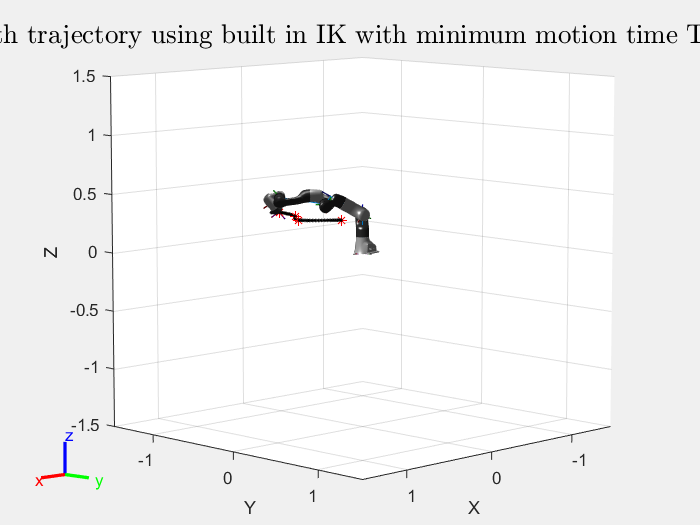

clf; figure;
set(gcf,'Visible','on')
show(robot, 'Visuals','on');
hold on;
rc = rateControl(sampleRate);
str = "Smooth trajectory using built in IK with minimum motion time T = " + num2str(tf) + " s";
title(str, FontSize=16, Interpreter="latex");
trajs_result = cell(1, numSamples);
for i = 1:numSamples
    show(robot,q(:,i),FastUpdate=true, PreservePlot=false);
    drawnow;
    hold on;

    T = FK_BodyForm(B, M, q(:,i));
    trajs_result{i} = T;
    X = T(1, 4);
    Y = T(2, 4);
    Z = T(3, 4);
    plot3(X, Y, Z, 'black.' );
    plot3(frankaSpaceWaypoints(1, :), frankaSpaceWaypoints(2, :), frankaSpaceWaypoints(3, :), 'r*');
    waitfor(rc);
    pause(0.01)
end

trajs_result{1}

ans =    -0.1709    0.3999   -0.9005    0.5000
    0.1831   -0.8851   -0.4278    0.2500
   -0.9681   -0.2380    0.0780    0.3500
         0         0         0    1.0000


trajs_result{20}

ans =     0.9375    0.0107   -0.3479    0.7493
    0.0333   -0.9977    0.0593    0.0108
   -0.3464   -0.0672   -0.9357    0.3500
         0         0         0    1.0000


trajs_result{40}

ans =     0.3972   -0.2891   -0.8710    0.6101
   -0.1960   -0.9539    0.2272   -0.1889
   -0.8966    0.0805   -0.4355    0.3500
         0         0         0    1.0000


trajs_result{60}

ans =     0.4323   -0.6523   -0.6226    0.5002
   -0.6919   -0.6827    0.2349   -0.4984
   -0.5782    0.3292   -0.7465    0.3500
         0         0         0    1.0000


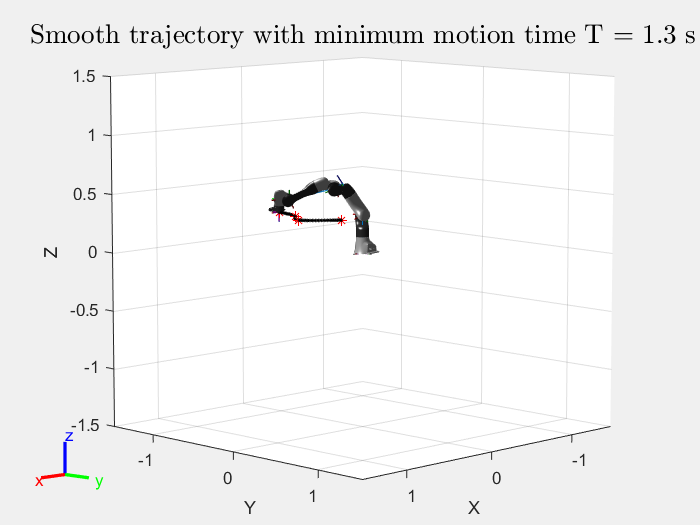

clf; figure;
set(gcf,'Visible','on')
show(robot, 'Visuals','on');
hold on;
rc = rateControl(sampleRate);
str = "Smooth trajectory with minimum motion time T = " + num2str(tf) + " s";
title(str, FontSize=16, Interpreter="latex");
trajs_result1 = cell(1, numSamples);
for i = 1:numSamples
    show(robot,q1(:,i),FastUpdate=true, PreservePlot=false);
    drawnow;
    hold on;

    T = FK_BodyForm(B, M, q1(:,i));
    trajs_result1{i} = T;
    X = T(1, 4);
    Y = T(2, 4);
    Z = T(3, 4);
    plot3(X, Y, Z, 'black.' );
    plot3(frankaSpaceWaypoints(1, :), frankaSpaceWaypoints(2, :), frankaSpaceWaypoints(3, :), 'r*');
    waitfor(rc);
    pause(0.01)
end

trajs_result1{5}

ans =     1.0000    0.0000    0.0001    0.5267
    0.0000   -1.0000   -0.0002    0.2302
    0.0001    0.0002   -1.0000    0.3499
         0         0         0    1.0000


trajs_result1{20}

ans =     1.0000    0.0001    0.0000    0.7491
    0.0001   -1.0000   -0.0000    0.0108
    0.0000    0.0000   -1.0000    0.3500
         0         0         0    1.0000


trajs_result1{40}

ans =     1.0000   -0.0000    0.0000    0.6099
   -0.0000   -1.0000    0.0001   -0.1887
    0.0000   -0.0001   -1.0000    0.3500
         0         0         0    1.0000


trajs_result1{60}

ans =     1.0000    0.0000    0.0000    0.5002
    0.0000   -1.0000    0.0000   -0.4983
    0.0000   -0.0000   -1.0000    0.3500
         0         0         0    1.0000


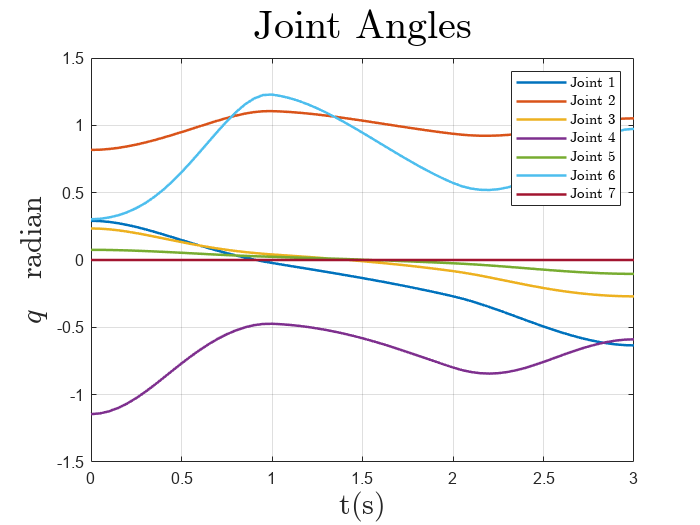


figure;

plot(t,q, LineWidth=1.5)
title('Joint Angles', Interpreter='latex', FontSize=24);
legend('Joint 1','Joint 2','Joint 3','Joint 4','Joint 5','Joint 6','Joint 7', 'Interpreter', 'latex');
ylabel('$q \quad \textrm{radian}$', Interpreter='latex', FontSize=18);
xlabel('t(s)', Interpreter='latex', FontSize=18);
grid on;

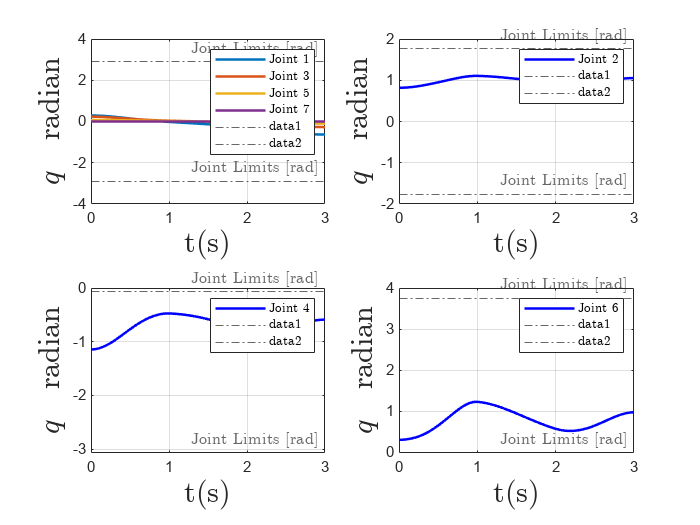

clf; figure;
title('Joint Angles', Interpreter='latex', FontSize=24);

subplot(2, 2, 1);
plot(t,q(1, :), LineWidth=1.5)
hold on;
plot(t,q(3, :), LineWidth=1.5)
hold on;
plot(t,q(5, :), LineWidth=1.5)
hold on;
plot(t,q(7, :), LineWidth=1.5)

legend('Joint 1','Joint 3','Joint 5','Joint 7', 'Interpreter', 'latex');
yline(panda.qlim(1, :),'-.','Joint Limits [rad]', Interpreter='latex');

ylabel('$q \quad \textrm{radian}$', Interpreter='latex', FontSize=18);
xlabel('t(s)', Interpreter='latex', FontSize=18);
grid on;


subplot(2, 2, 2);
plot(t,q(2, :), LineWidth=1.5, Color='b')
legend('Joint 2', 'Interpreter', 'latex');
yline(panda.qlim(2, :),'-.','Joint Limits [rad]', Interpreter='latex');
ylabel('$q \quad \textrm{radian}$', Interpreter='latex', FontSize=18);
xlabel('t(s)', Interpreter='latex', FontSize=18);
grid on;

subplot(2, 2, 3);
plot(t,q(4, :), LineWidth=1.5, Color='b')
legend('Joint 4', 'Interpreter', 'latex');
yline(panda.qlim(4, :),'-.','Joint Limits [rad]', Interpreter='latex');
ylabel('$q \quad \textrm{radian}$', Interpreter='latex', FontSize=18);
xlabel('t(s)', Interpreter='latex', FontSize=18);
grid on;

subplot(2, 2, 4);
plot(t,q(6, :), LineWidth=1.5, Color='b')
legend('Joint 6', 'Interpreter', 'latex');
yline(panda.qlim(6, :),'-.','Joint Limits [rad]', Interpreter='latex');
ylabel('$q \quad \textrm{radian}$', Interpreter='latex', FontSize=18);
xlabel('t(s)', Interpreter='latex', FontSize=18);
grid on;

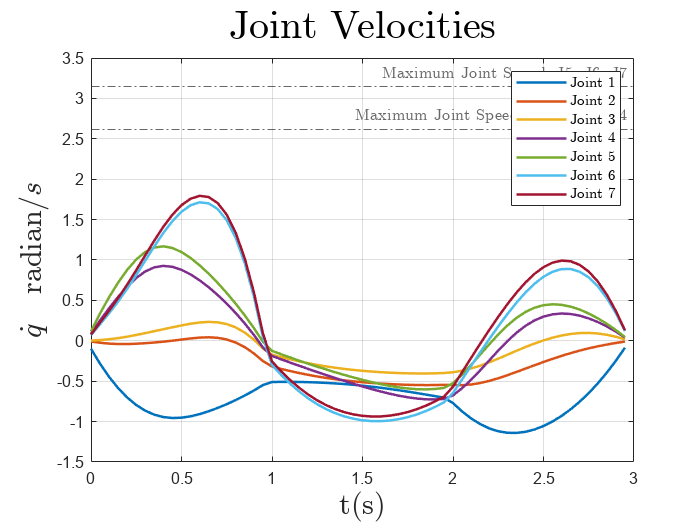


qd  = diff(q, 1, 2)./dt;
qd = smoothdata(qd,"movmean","SmoothingFactor",0.5);
qdd = diff(qd, 1, 2)./dt;
qdd = smoothdata(qdd,"movmean","SmoothingFactor",0.5);

figure;
td = t(1: numSamples-1);
plot(td,qd, LineWidth=1.5)



yline(peakVelocities(1),'-.','Maximum Joint Speed, J1, J2, J3, J4', Interpreter='latex');
yline(peakVelocities(5),'-.','Maximum Joint Speed, J5, J6, J7', Interpreter='latex');



title('Joint Velocities', Interpreter='latex', FontSize=24);
legend('Joint 1','Joint 2','Joint 3','Joint 4','Joint 5','Joint 6','Joint 7', 'Interpreter', 'latex');
ylabel("$\dot{q} \quad {\textrm{radian}}/{s}$", Interpreter='latex', FontSize=18);
xlabel('t(s)', Interpreter='latex', FontSize=18);
grid on;

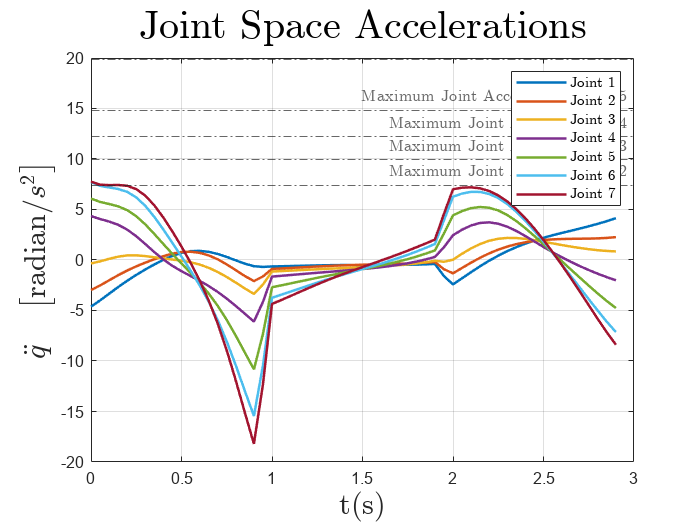


figure;
tdd = t(1:numSamples-2);

plot(tdd,qdd, LineWidth=1.5)

hold on;

yline(peakAcceleration(1),'-.','Maximum Joint Acceleration, J1, J5', Interpreter='latex');
yline(peakAcceleration(2),'-.','Maximum Joint Acceleration, J2', Interpreter='latex');
yline(peakAcceleration(3),'-.','Maximum Joint Acceleration, J3', Interpreter='latex');
yline(peakAcceleration(4),'-.','Maximum Joint Acceleration, J4', Interpreter='latex');
yline(peakAcceleration(6),'-.','Maximum Joint Acceleration, J6, J7', Interpreter='latex');

title('Joint Space Accelerations', Interpreter='latex', FontSize=24);
legend('Joint 1','Joint 2','Joint 3','Joint 4','Joint 5','Joint 6','Joint 7', 'Interpreter', 'latex');
ylabel('$\ddot{q} \quad \left[ \textrm{radian}/ s^2 \right]$', Interpreter='latex', FontSize=18);
xlabel('t(s)', Interpreter='latex', FontSize=18);

grid on;

### B-Spline Trajectory

A B-spline polynomial results in smooth, continuous motion, and is predominantly used for task-space applications. You can create this trajectory by using the [`bsplinepolytraj`](docid:robotics_ref#mw_dcee2074-da2d-4a77-aedc-3ef5a39d073d) function. Unlike the other trajectories, which interpolate the waypoints that define them, a B-spline is defined by a set of control points. The resulting trajectory hits only the initial and final control points, but falls in the convex hull of the complete set of control points. 

Apply the previously used waypoints as the control points.

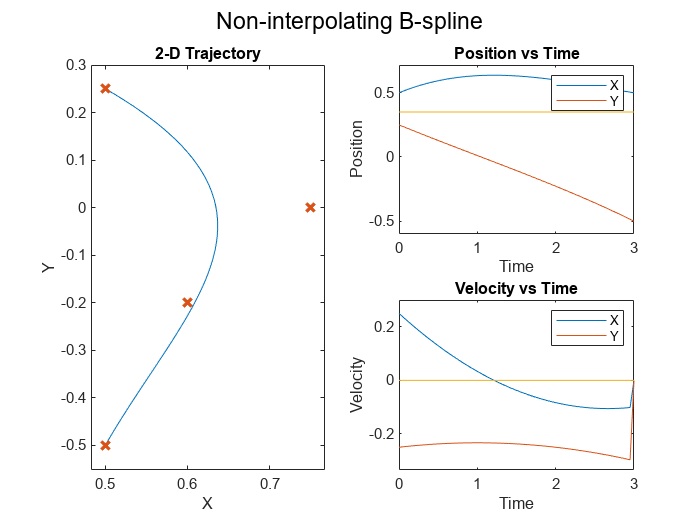

[pos,vel] = bsplinepolytraj(wpts,tpts([1 end]),t);
helperPlotTaskSpaceTraj('Non-interpolating B-spline',t,pos,vel,wpts);

You can create an interpolating B-spline by deriving a new set of control points from the original waypoints, which the B-spline polynomial interpolates with the original waypoints. Like the standard B-spline, use this polynomial primarily for task-space applications. 

Use the `helperCreateControlPointsFromWaypoints` helper function to derive the new control points.

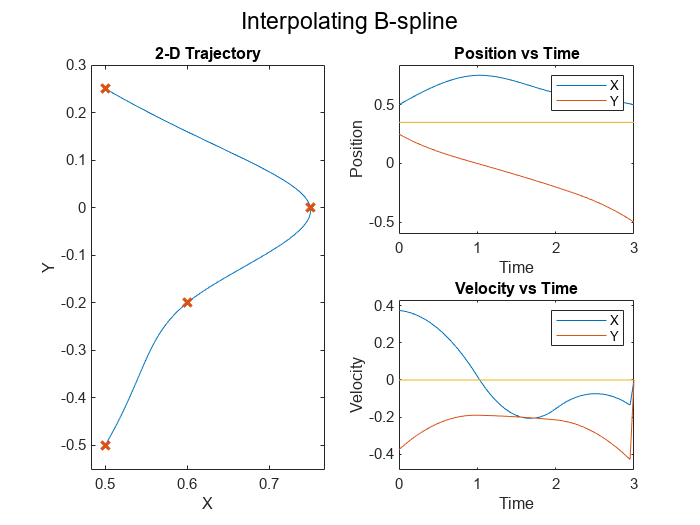

cpts = helperCreateControlPointsFromWaypoints(wpts);
[pos,vel] = bsplinepolytraj(cpts,tpts([1 end]),t);
helperPlotTaskSpaceTraj('Interpolating B-spline',t,pos,vel,wpts);

Use the [`inverseKinematics`](docid:robotics_ref#bvdhj7x-1) function to create an inverse kinematics solver and solve for configurations that reach the desired end-effector positions over the trajectory.

rng(0) % Seed the RNG so the inverse kinematics solution is consistent
ik = inverseKinematics(RigidBodyTree=robot);
ik.SolverParameters.AllowRandomRestart = false;
q = zeros(7,numSamples);
weights = [0 0 0 1 1 1]; % Prioritize position over orientation
initialGuess = [0, 0, 0, -pi/2, 0, 0, 0]'; % Choose an inital guess within the robot joint limits

trajs = cell(1, size(pos,2));

for i = 1:size(pos,2)
    targetPose = trvec2tform(pos(:,i)')*eul2tform([0, 0, pi]);
    trajs{i} = targetPose;

    q(:,i) = ik('b_frame',targetPose,weights,initialGuess);
    initialGuess = q(:,i); % Use the last result as the next initial guess
end


for i = 1:size(pos,2)
    q1(:,i) = IK_Body(trajs{i}, initialGuess, [1e-3, 1e-3], B, M);
    initialGuess = q1(:,i); % Use the last result as the next initial guess
end

Show the results using the robot model.

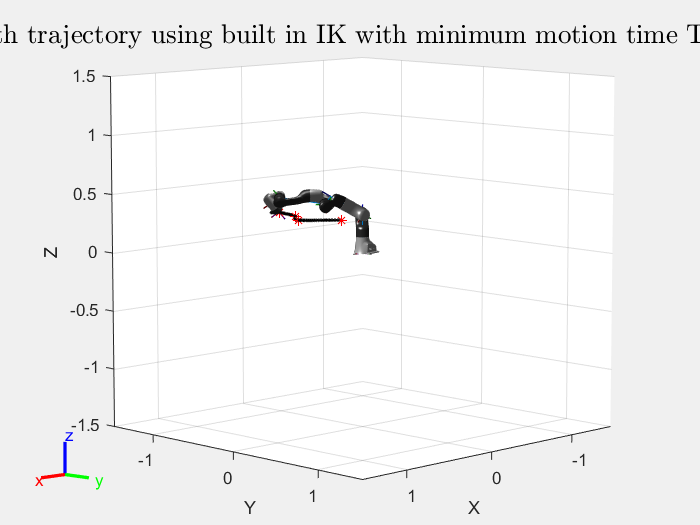

clf; figure;
set(gcf,'Visible','on')
show(robot, 'Visuals','on');
hold on;
rc = rateControl(sampleRate);
str = "Smooth trajectory using built in IK with minimum motion time T = " + num2str(tf) + " s";
title(str, FontSize=16, Interpreter="latex");
trajs_result = cell(1, numSamples);
for i = 1:numSamples
    show(robot,q(:,i),FastUpdate=true, PreservePlot=false);
    drawnow;
    hold on;

    T = FK_BodyForm(B, M, q(:,i));
    trajs_result{i} = T;
    X = T(1, 4);
    Y = T(2, 4);
    Z = T(3, 4);
    plot3(X, Y, Z, 'black.' );
    plot3(frankaSpaceWaypoints(1, :), frankaSpaceWaypoints(2, :), frankaSpaceWaypoints(3, :), 'r*');
    waitfor(rc);
    pause(0.01)
end

trajs_result{1}

ans =    -0.1709    0.3999   -0.9005    0.5000
    0.1831   -0.8851   -0.4278    0.2500
   -0.9681   -0.2380    0.0780    0.3500
         0         0         0    1.0000


trajs_result{20}

ans =     0.9347    0.0090   -0.3554    0.7482
    0.0313   -0.9979    0.0571    0.0095
   -0.3541   -0.0645   -0.9330    0.3500
         0         0         0    1.0000


trajs_result{40}

ans =     0.3864   -0.2902   -0.8755    0.6081
   -0.1956   -0.9534    0.2297   -0.1893
   -0.9014    0.0825   -0.4251    0.3500
         0         0         0    1.0000


trajs_result{60}

ans =     0.4184   -0.6366   -0.6479    0.5071
   -0.6576   -0.7043    0.2674   -0.4780
   -0.6265    0.3142   -0.7133    0.3500
         0         0         0    1.0000


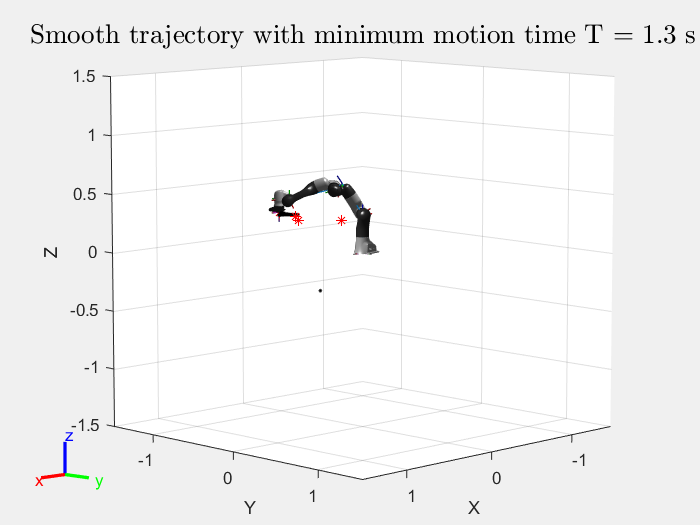

clf; figure;
set(gcf,'Visible','on')
show(robot, 'Visuals','on');
hold on;
rc = rateControl(sampleRate);
str = "Smooth trajectory with minimum motion time T = " + num2str(tf) + " s";
title(str, FontSize=16, Interpreter="latex");
trajs_result1 = cell(1, numSamples);
for i = 1:numSamples
    show(robot,q1(:,i),FastUpdate=true, PreservePlot=false);
    drawnow;
    hold on;

    T = FK_BodyForm(B, M, q1(:,i));
    trajs_result1{i} = T;
    X = T(1, 4);
    Y = T(2, 4);
    Z = T(3, 4);
    plot3(X, Y, Z, 'black.' );
    plot3(frankaSpaceWaypoints(1, :), frankaSpaceWaypoints(2, :), frankaSpaceWaypoints(3, :), 'r*');
    waitfor(rc);
    pause(0.01)
end

trajs_result1{5}

ans =     0.7024   -0.7103   -0.0453    0.5328
   -0.7110   -0.6972   -0.0920   -0.2791
    0.0338    0.0968   -0.9947    0.3516
         0         0         0    1.0000


trajs_result1{20}

ans =     0.9069   -0.4191   -0.0434    0.6833
   -0.4211   -0.8987   -0.1225   -0.3045
    0.0123    0.1294   -0.9915    0.3578
         0         0         0    1.0000


trajs_result1{40}

ans =     0.9861   -0.1658   -0.0078    0.5684
   -0.1660   -0.9858   -0.0267   -0.2871
   -0.0032    0.0276   -0.9996    0.3533
         0         0         0    1.0000


trajs_result1{60}

ans =     1.0000    0.0004    0.0000    0.5067
    0.0004   -1.0000    0.0000   -0.4778
    0.0000   -0.0000   -1.0000    0.3499
         0         0         0    1.0000


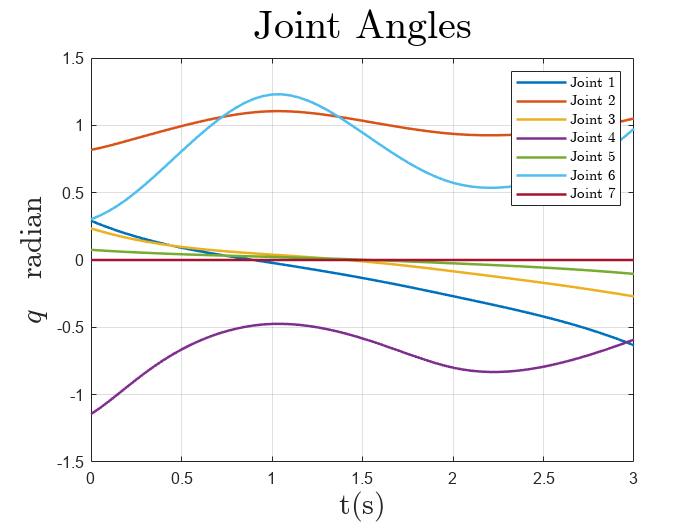


figure;

plot(t,q, LineWidth=1.5)
title('Joint Angles', Interpreter='latex', FontSize=24);
legend('Joint 1','Joint 2','Joint 3','Joint 4','Joint 5','Joint 6','Joint 7', 'Interpreter', 'latex');
ylabel('$q \quad \textrm{radian}$', Interpreter='latex', FontSize=18);
xlabel('t(s)', Interpreter='latex', FontSize=18);
grid on;

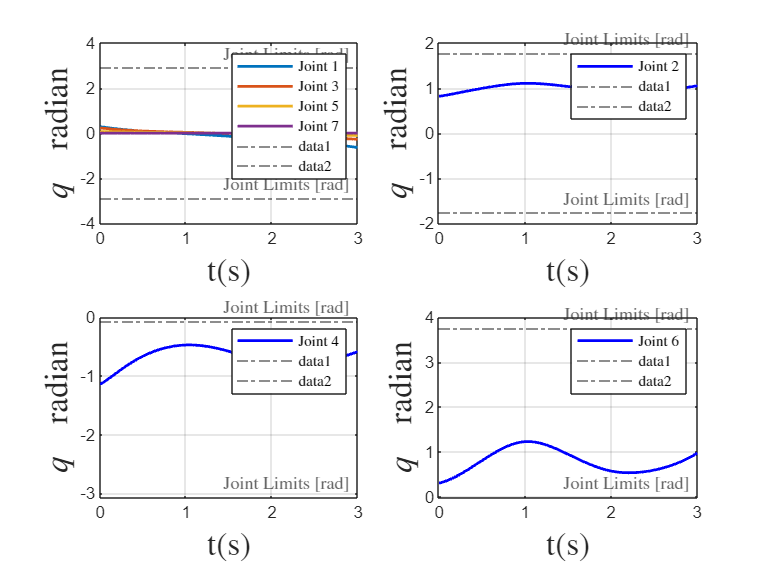

clf; figure;
title('Joint Angles', Interpreter='latex', FontSize=24);

subplot(2, 2, 1);
plot(t,q(1, :), LineWidth=1.5)
hold on;
plot(t,q(3, :), LineWidth=1.5)
hold on;
plot(t,q(5, :), LineWidth=1.5)
hold on;
plot(t,q(7, :), LineWidth=1.5)

legend('Joint 1','Joint 3','Joint 5','Joint 7', 'Interpreter', 'latex');
yline(panda.qlim(1, :),'-.','Joint Limits [rad]', Interpreter='latex');

ylabel('$q \quad \textrm{radian}$', Interpreter='latex', FontSize=18);
xlabel('t(s)', Interpreter='latex', FontSize=18);
grid on;


subplot(2, 2, 2);
plot(t,q(2, :), LineWidth=1.5, Color='b')
legend('Joint 2', 'Interpreter', 'latex');
yline(panda.qlim(2, :),'-.','Joint Limits [rad]', Interpreter='latex');
ylabel('$q \quad \textrm{radian}$', Interpreter='latex', FontSize=18);
xlabel('t(s)', Interpreter='latex', FontSize=18);
grid on;

subplot(2, 2, 3);
plot(t,q(4, :), LineWidth=1.5, Color='b')
legend('Joint 4', 'Interpreter', 'latex');
yline(panda.qlim(4, :),'-.','Joint Limits [rad]', Interpreter='latex');
ylabel('$q \quad \textrm{radian}$', Interpreter='latex', FontSize=18);
xlabel('t(s)', Interpreter='latex', FontSize=18);
grid on;

subplot(2, 2, 4);
plot(t,q(6, :), LineWidth=1.5, Color='b')
legend('Joint 6', 'Interpreter', 'latex');
yline(panda.qlim(6, :),'-.','Joint Limits [rad]', Interpreter='latex');
ylabel('$q \quad \textrm{radian}$', Interpreter='latex', FontSize=18);
xlabel('t(s)', Interpreter='latex', FontSize=18);
grid on;

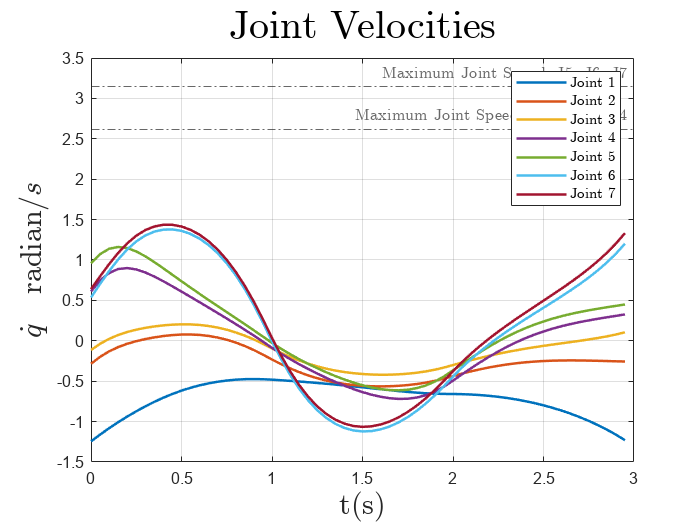


qd  = diff(q, 1, 2)./dt;
qd = smoothdata(qd,"movmean","SmoothingFactor",0.5);
qdd = diff(qd, 1, 2)./dt;
qdd = smoothdata(qdd,"movmean","SmoothingFactor",0.5);

figure;
td = t(1: numSamples-1);
plot(td,qd, LineWidth=1.5)



yline(peakVelocities(1),'-.','Maximum Joint Speed, J1, J2, J3, J4', Interpreter='latex');
yline(peakVelocities(5),'-.','Maximum Joint Speed, J5, J6, J7', Interpreter='latex');



title('Joint Velocities', Interpreter='latex', FontSize=24);
legend('Joint 1','Joint 2','Joint 3','Joint 4','Joint 5','Joint 6','Joint 7', 'Interpreter', 'latex');
ylabel("$\dot{q} \quad {\textrm{radian}}/{s}$", Interpreter='latex', FontSize=18);
xlabel('t(s)', Interpreter='latex', FontSize=18);
grid on;

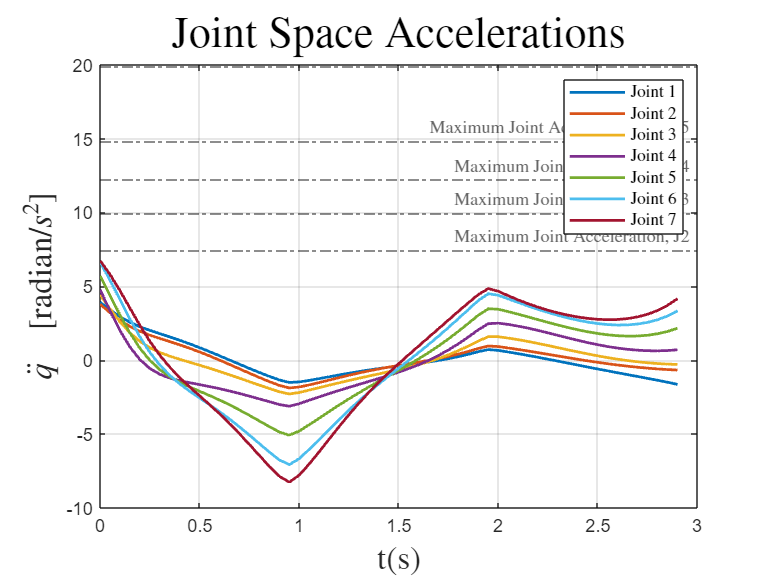


figure;
tdd = t(1:numSamples-2);

plot(tdd,qdd, LineWidth=1.5)

hold on;

yline(peakAcceleration(1),'-.','Maximum Joint Acceleration, J1, J5', Interpreter='latex');
yline(peakAcceleration(2),'-.','Maximum Joint Acceleration, J2', Interpreter='latex');
yline(peakAcceleration(3),'-.','Maximum Joint Acceleration, J3', Interpreter='latex');
yline(peakAcceleration(4),'-.','Maximum Joint Acceleration, J4', Interpreter='latex');
yline(peakAcceleration(6),'-.','Maximum Joint Acceleration, J6, J7', Interpreter='latex');

title('Joint Space Accelerations', Interpreter='latex', FontSize=24);
legend('Joint 1','Joint 2','Joint 3','Joint 4','Joint 5','Joint 6','Joint 7', 'Interpreter', 'latex');
ylabel('$\ddot{q} \quad \left[ \textrm{radian}/ s^2 \right]$', Interpreter='latex', FontSize=18);
xlabel('t(s)', Interpreter='latex', FontSize=18);

grid on;

*Copyright 2021 The MathWorks, Inc.*